modulePath = 'C:/Users/Asus/Studia/IPS - Projekt/dane - semestr 5/MATLAB_project/python_modules';
insert(py.sys.path, int32(0), modulePath);
load("C:\Users\Asus\Studia\IPS - Projekt\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat");

function pred_vector = model_chronos_expanding(y_train, y_test, step_length)
    modul = py.importlib.import_module('chronos_module_window');
    
    py.importlib.reload(modul);

    y_train_list = py.list(y_train(:)'); 
    y_test_list  = py.list(y_test(:)');
    
    result_list = modul.run_forecast_expanding(y_train_list, y_test_list, int32(step_length));
    
    pred_vector = result_list.double;
end

% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);

dlugosc_testu_oryginalna = 2880;

train_data = ab_diff_train_norm;
% test_data = ab_diff_test_norm(1:dlugosc_testu_oryginalna);
test_data = ab_diff_test_norm;


step_length = 1

step_length = 1

% Przewidywania A1 - model hybrydowy
predictions = model_chronos_expanding(train_data, test_data, step_length)

CUDA dostepne: True
Wersja: 2.9.1+cu126
Ładowanie modelu Chronos-2 (Singleton)...
`torch_dtype` is deprecated! Use `dtype` instead!
`torch_dtype` is deprecated! Use `dtype` instead!
[Python Chronos] Start Expanding Window. Kroki: 17375, Step: 1
[Python Chronos] Krok 1/17375
[Python Chronos] Krok 2/17375
[Python Chronos] Krok 3/17375
[Python Chronos] Krok 4/17375
[Python Chronos] Krok 5/17375
[Python Chronos] Krok 6/17375
[Python Chronos] Krok 7/17375
[Python Chronos] Krok 8/17375
[Python Chronos] Krok 9/17375
[Python Chronos] Krok 10/17375
[Python Chronos] Krok 11/17375
[Python Chronos] Krok 12/17375
[Python Chronos] Krok 13/17375
[Python Chronos] Krok 14/17375
[Python Chronos] Krok 15/17375
[Python Chronos] Krok 16/17375
[Python Chronos] Krok 17/17375
[Python Chronos] Krok 18/17375
[Python Chronos] Krok 19/17375
[Python Chronos] Krok 20/17375
[Python Chronos] Krok 21/17375
[Python Chronos] Krok 22/17375
[Python Chronos] Krok 23/17375
[Python Chronos] Krok 24/17375
[Python Chronos] Kro

predictions =     0.1641    0.1338    0.1641    0.1719    0.1855    0.1201    0.0752    0.0840    0.0820    0.0767    0.0820    0.0835    0.0889    0.0869    0.0854    0.0820    0.6562    0.8047    0.4570    0.0713    0.0659    0.0713    0.0732    0.0786    0.0752    0.0698    0.0713    0.0874    0.1167    0.1011    0.3867    0.1592    0.1807    0.1572    0.1602    0.2422    0.1807    0.7969    0.8555    0.2988    0.0732    0.0767    0.0732    0.0679    0.0698    0.0698    0.0693    0.0659    0.0713    0.0693


predictions = predictions'

predictions =     0.1641
    0.1338
    0.1641
    0.1719
    0.1855
    0.1201
    0.0752
    0.0840
    0.0820
    0.0767
    0.0820
    0.0835
    0.0889
    0.0869
    0.0854



mae_score = mae(test_data, predictions)

mae_score = 0.0488

mape_score = mape(test_data, predictions)

mape_score = 27.2195

rmse_score = rmse(test_data, predictions)

rmse_score = 0.1460

r2_classic = R2_classic(test_data, predictions)

r2_classic = 0.9242

r2_alt = R2_alt(test_data, predictions)

r2_alt = 0.9534

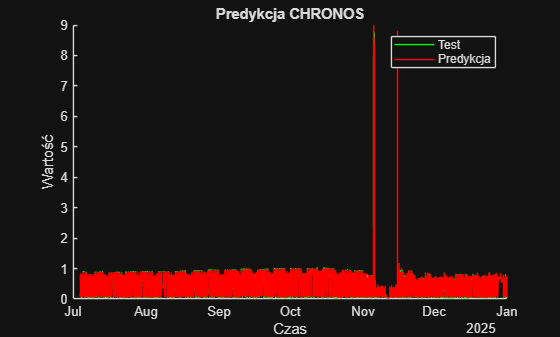


figure;
hold on;
%plot(ab_diff_train.Time, ab_diff_train_norm, 'Color','blue','DisplayName','Trening');
plot(ab_diff_test.Time(1:length(predictions)), ab_diff_test_norm(1:length(predictions)), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:length(predictions)), predictions, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja CHRONOS")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time, ...
                   ab_diff_test_norm, ...
                   predictions, ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'});

writetable(T_z_czasem, "pred_ab_CHRONOS_month_"+ num2str(step_length)+".xlsx");